sigma = bank angle

Beta = Vehicle Ballistic Coefficient

m = vehicle mass

A = reference area

q = dynamic pressure

rho = atmospheric density

Omega = planet rotation rate

V = planet relative vehicle speed

L = Lift force

D = drag force

gr gtheta gphi = radial, longitudinal, latitudinal components gravitational acceleration

U = gravitational accelaration

Vinf = arrival velocity

Vei = velocity intertial entry

delta = declination

re = atmospheric interference radius

find a function for density

rhodata = load('mars-gram-avg.dat')

rhodata = 	1.0e+05 *

         0    0.0023    0.0057    0.0000    0.0024
    0.0100    0.0022    0.0052    0.0000    0.0023
    0.0200    0.0022    0.0047    0.0000    0.0023
    0.0300    0.0022    0.0043    0.0000    0.0023
    0.0400    0.0021    0.0039    0.0000    0.0023
    0.0500    0.0021    0.0036    0.0000    0.0023
    0.0600    0.0021    0.0032    0.0000    0.0023
    0.0700    0.0021    0.0029    0.0000    0.0022
    0.0800    0.0020    0.0026    0.0000    0.0022
    0.0900    0.0020    0.0024    0.0000    0.0022


alt = rhodata(:,1)

alt =            0
        1000
        2000
        3000
        4000
        5000
        6000
        7000
        8000
        9000


rho = rhodata(:,4)

rho =     0.0132
    0.0122
    0.0113
    0.0105
    0.0097
    0.0090
    0.0082
    0.0075
    0.0069
    0.0063


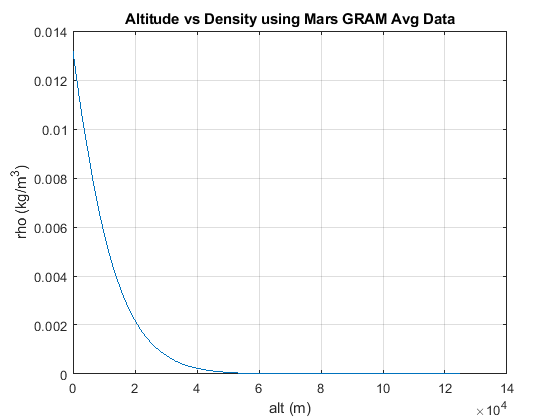

plot(alt,rho)
xlabel('alt (m)')
ylabel('rho (kg/m^3)')
grid on
title('Altitude vs Density using Mars GRAM Avg Data')

Some initial values

gamma = deg2rad(-12)

gamma = -0.2094

r_mars =  3389.5 % in km

r_mars = 3.3895e+03

Setup independent variable r

r_surf = linspace(0,125,1000)

r_surf =          0    0.1251    0.2503    0.3754    0.5005    0.6256    0.7508    0.8759    1.0010    1.1261    1.2513    1.3764    1.5015    1.6266    1.7518    1.8769    2.0020    2.1271    2.2523    2.3774    2.5025    2.6276    2.7528    2.8779    3.0030    3.1281    3.2533    3.3784    3.5035    3.6286    3.7538    3.8789    4.0040    4.1291    4.2543    4.3794    4.5045    4.6296    4.7548    4.8799    5.0050    5.1301    5.2553    5.3804    5.5055    5.6306    5.7558    5.8809    6.0060    6.1311


r = r_mars + r_surf

r = 	1.0e+03 *

    3.3895    3.3896    3.3898    3.3899    3.3900    3.3901    3.3903    3.3904    3.3905    3.3906    3.3908    3.3909    3.3910    3.3911    3.3913    3.3914    3.3915    3.3916    3.3918    3.3919    3.3920    3.3921    3.3923    3.3924    3.3925    3.3926    3.3928    3.3929    3.3930    3.3931    3.3933    3.3934    3.3935    3.3936    3.3938    3.3939    3.3940    3.3941    3.3943    3.3944    3.3945    3.3946    3.3948    3.3949    3.3950    3.3951    3.3953    3.3954    3.3955    3.3956


m = 22,633.00

m = 22

ans = 633

mup = 4.282837*10^4 %km^3/s^2

mup = 4.2828e+04

Vinf = 5 % got from cycler information 

Vinf = 5

Set dependents

U = mup/r % neglecting J terms, which make gtheta and gphi terms zero

Error using  / 
Matrix dimensions must agree.

gr = -mup/r^2%dU/dr
Vei = 5.5 % km/s Vinf^2 + 2*mup/re
Beta = m/(CD*A)

find rho by making interpolation function based off data file

CD and A from taxi design

q = 1/2*rho*V^2
CD = D/(q*A)


ignore planetary spin effects for now

Vdot (need to define D still?)

Vdot = -q/Beta + gr*sin(gamma) % + gtheta*cos(gamma)*cos(psi) + Omega^2*r*cos(phi)*(sin(gamma)*cos(phi)-cos(gamma)*sin(phi)*sin(psi))
Vdot = -D/m-mup/r^2*sin(gamma)

How to get V from Vdot?

https://www.faa.gov/about/office_org/headquarters_offices/avs/offices/aam/cami/library/online_libraries/aerospace_medicine/tutorial/media/III.4.1.7_Returning_from_Space.pdf  

%V = integral(Vdot,)

Convert 6 equations to state space using r theta phi 

use a couple of cases for L/D approx 0.8-1

can set up bank angle to 0 initially (control variable)

find an atmospheric terminal velocity

intial conditions r

heating equations for venus similar to mars'

to find the downrange create sdot variable = Vcos(gamma)